訓練データ　テストデータ

bulkOutLim以上のタイムステップを持っていたら水増し()に使う

cd(rootdir)
cd("vars")
load("Co_infoTbl_3_2.mat","Co_infoTbl")
cd(rootdir)
completeIdx=find(Co_infoTbl.isComplete);

divideRatio=0.9;
divideIdx=round(length(completeIdx)*divideRatio);

augmentLim=200;
augmentPoint=[0.05,0.1,0.15,0.2,0.25];

XTrain={};
YTrain={};
XTest={};
YTest={};
for i=1:divideIdx

Trainは1タイムステップ後

    XTrain{end+1,1}=Co_infoTbl.dataset{completeIdx(i)}(1:end-1,:)';
    YTrain{end+1,1}=Co_infoTbl.dataset{completeIdx(i)}(2:end,:)';
    datasetLen=length(Co_infoTbl.dataset{completeIdx(i)});
    if datasetLen>=augmentLim
        tmpPoint=arrayfun(@(x) round(datasetLen*x),augmentPoint);
        for j=1:length(tmpPoint)
            XTrain{end+1,1}=Co_infoTbl.dataset{completeIdx(i)}(tmpPoint(j):end-1-tmpPoint(length(tmpPoint)-(j-1)),:)';
            YTrain{end+1,1}=Co_infoTbl.dataset{completeIdx(i)}(tmpPoint(j)+1:end-tmpPoint(length(tmpPoint)-(j-1)),:)';
        end
    end
end

Testは8タイムステップ後

predStep=8;
for i=divideIdx+1:length(completeIdx)
    XTest{end+1,1}=Co_infoTbl.dataset{completeIdx(i)}(1:end-(predStep-1),:)';
    YTest{end+1,1}=Co_infoTbl.dataset{completeIdx(i)}(1:end,:)';
end
clear augmentLim augmentPoint divideIdx divideRatio datasetLen tmpPoint i j completeIdx

numFeatures = length(XTrain{1}(:,1));
numResponses = length(YTrain{1}(:,1));
numHiddenUnits = 100;
layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits,'OutputMode',"sequence")
    fullyConnectedLayer(numResponses)
    regressionLayer];
miniBatchSize = 256;
options = trainingOptions('adam', ...
    'MaxEpochs',30, ...
    'InitialLearnRate',0.001, ...
    "LearnRateSchedule","none",...
    "MiniBatchSize",miniBatchSize,...
    'Verbose',0, ...
    'Plots',"training-progress");

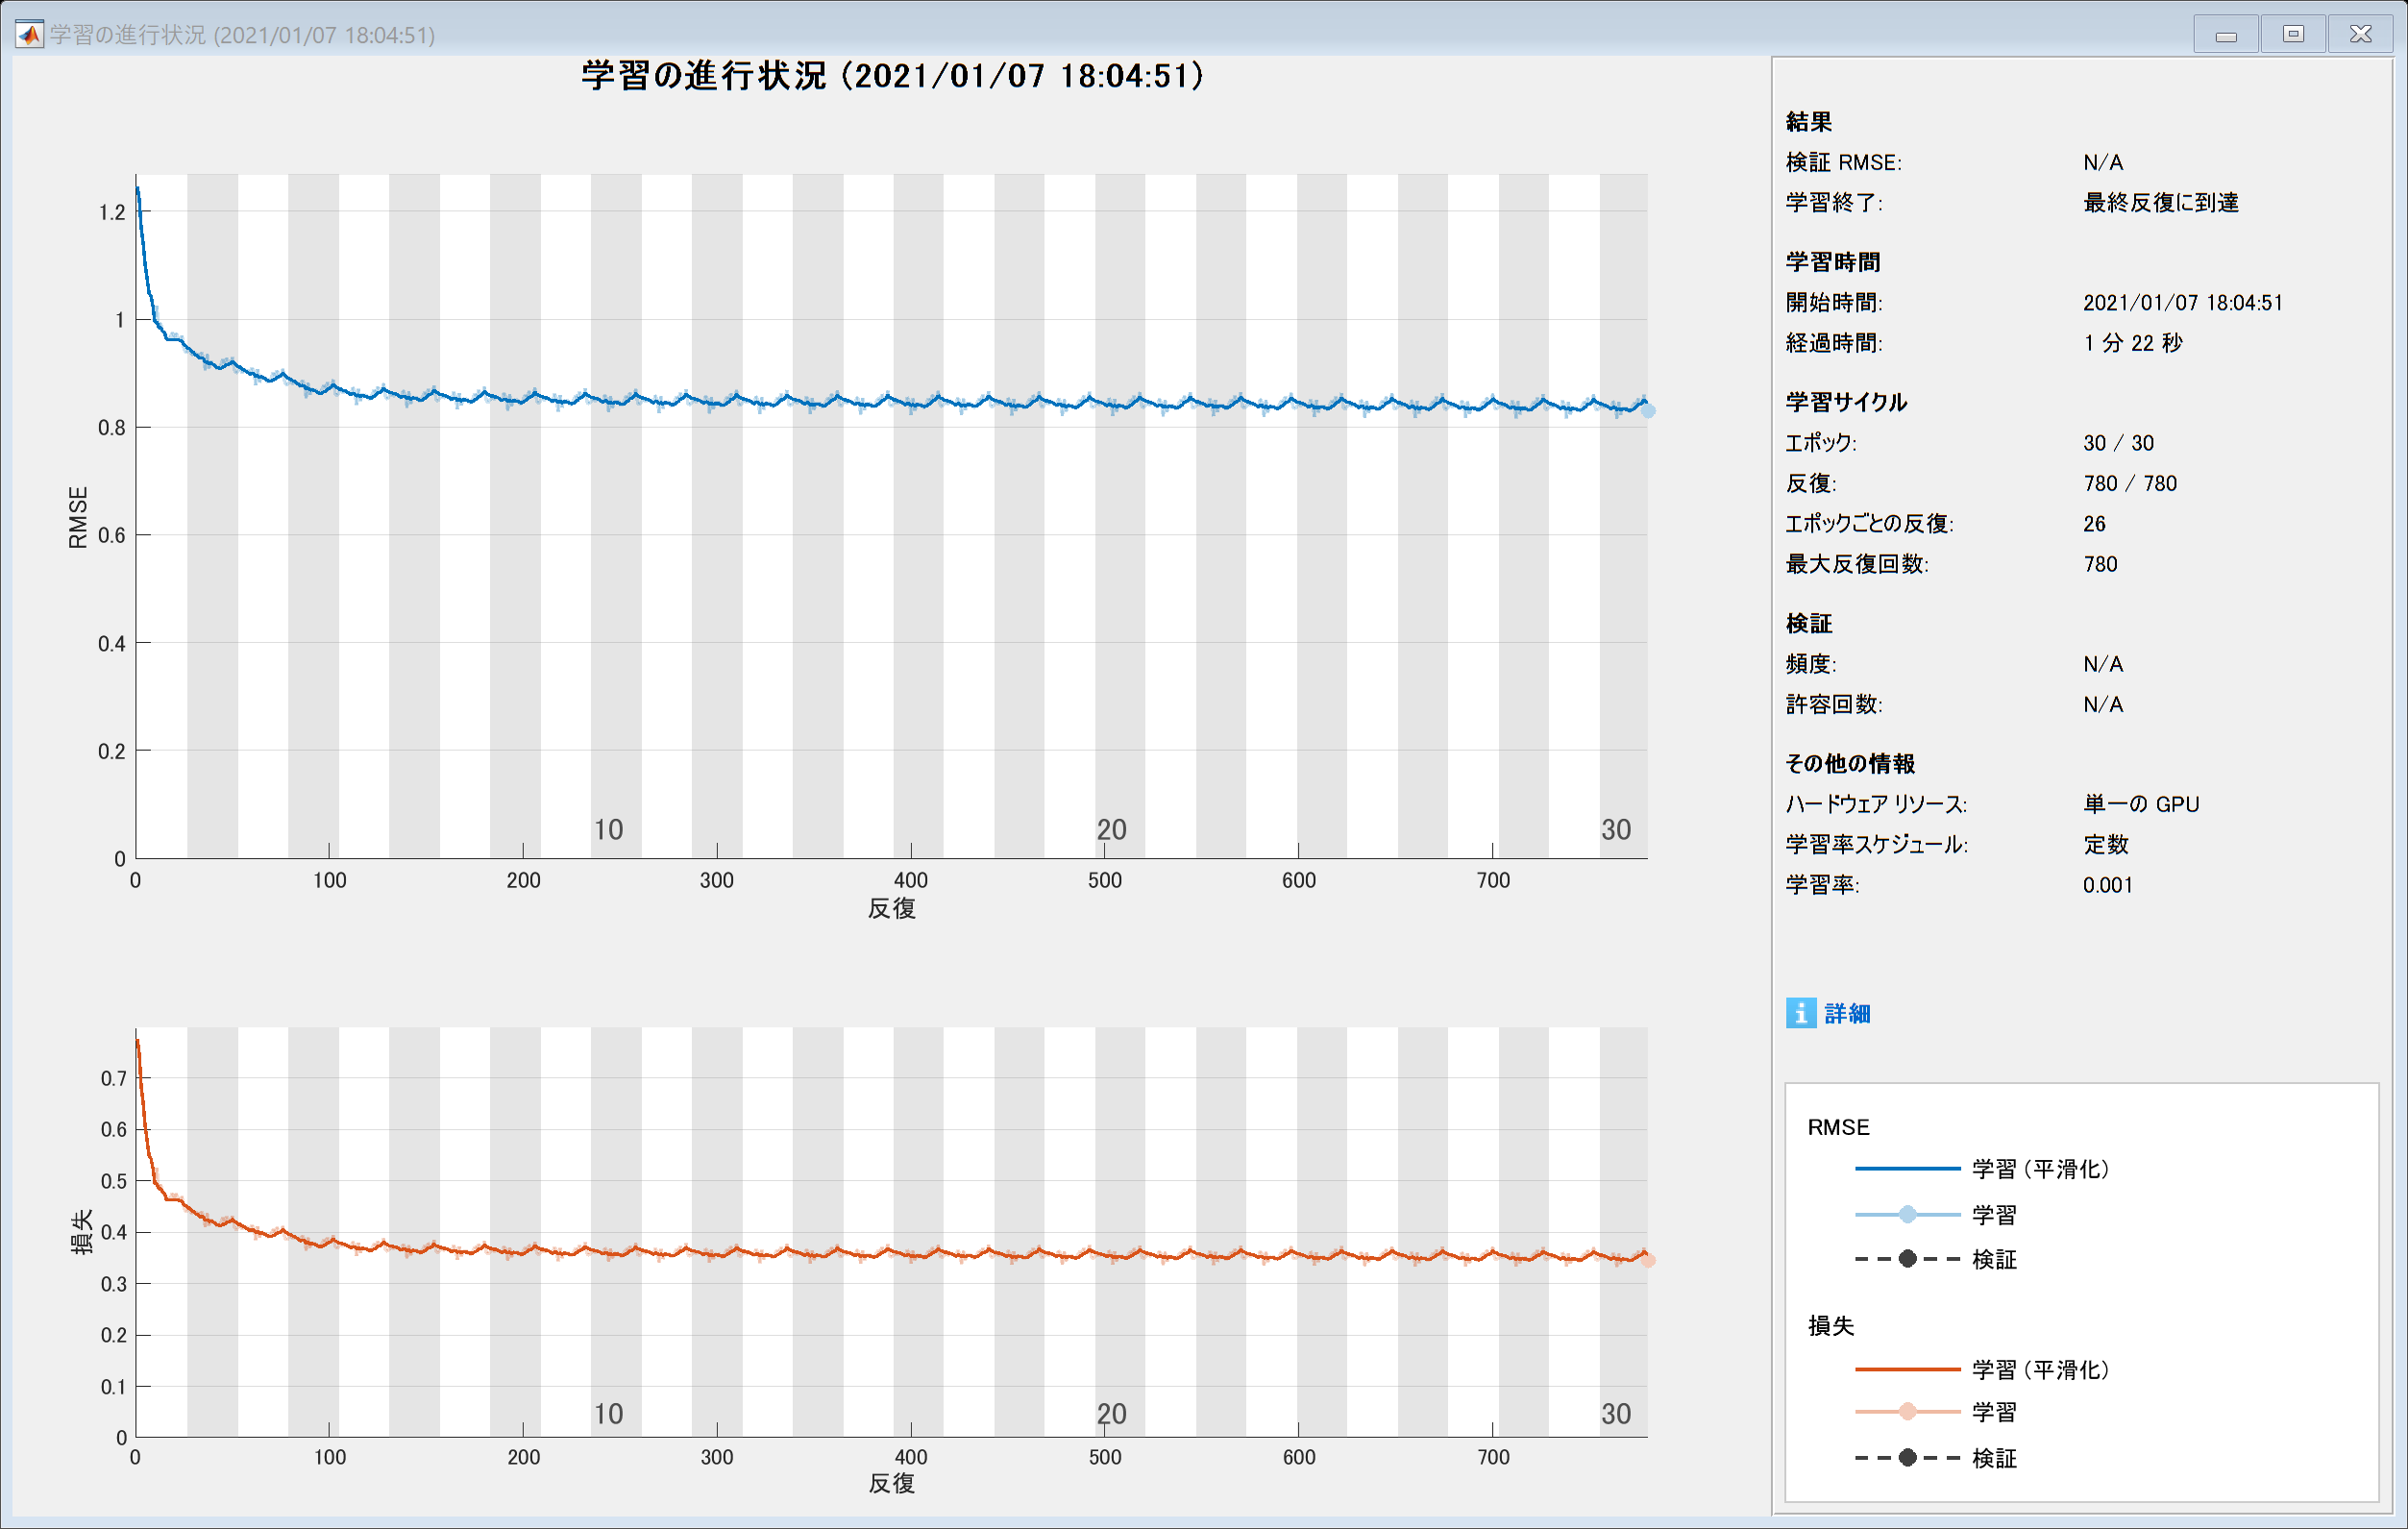

net =   SeriesNetwork のプロパティ:

         Layers: [4×1 nnet.cnn.layer.Layer]
     InputNames: {'sequenceinput'}
    OutputNames: {'regressionoutput'}


net = trainNetwork(XTrain,YTrain,layers,options)

testTbl=predTest(net,XTest,YTest,predStep);

エラー: DAGNetwork/predictAndUpdateState (line 114)
CUDA デバイスのプロパティを取得中に予期しないエラーが発生しました。CUDA エラー:
CUDA_ERROR_UNKNOWN

エラー: SeriesNetwork/predictAndUpdateState (line 376)
            [this.UnderlyingDAGNetwork, Y] = this.UnderlyingDAGNetwork.predictAndUpdateState(X, varargin{:});

エラー: 

diffBool=false([height(testTbl),1]);
for i=1:height(testTbl)
    predDiff(i)=testTbl.pred{i}(end)-testTbl.rightY{i}(1,end-predStep);
    rightDiff(i)=testTbl.rightY{i}(end)-testTbl.rightY{i}(1,end-predStep);
    if ~xor(predDiff(i)>0,rightDiff(i)>0)
        diffBool(i)=true;
    end
    testTbl.rmse(i)=immse(testTbl.rightY{i}(:,[end-(predStep-1):end]),testTbl.pred{i});
end
diffTbl=table(rightDiff',predDiff',diffBool);
nnz(diffBool)/length(diffBool)

ans = 0.9008

rmse_both=table(testTbl_stock.rmse,testTbl_trend.rmse);
rmse_both.diff=rmse_both{:,1}-rmse_both{:,2};
rmse_both.bool=rmse_both{:,3}>0;

nnz(rmse_both.bool)/height(rmse_both)

ans = 0.5267

function testTbl=predTest(net,XTest,YTest,predStep)
    testTbl=table('Size',[length(XTest),2],'VariableTypes',{'cell','cell'},'VariableNames',{'rightY','pred'});
    for i=1:length(XTest)
        tmpPred=[];
        net = resetState(net);
        [net,YPred] = predictAndUpdateState(net,XTest{i});
        tmpPred=[tmpPred YPred(:,end)];
        for j=1:predStep-1
            [net,YPred] = predictAndUpdateState(net,tmpPred);
            tmpPred=[tmpPred YPred(:,end)];
        end
        testTbl.rightY(i)=YTest(i);
        testTbl.pred(i)={double(tmpPred)};
    end
end
